# Práctica 2

## Desarrollo

### Problema 3

Repite el problema anterior pero para conjuntos difusos en tiempo discreto.  

Prueba esta función con los conjuntos difusos (A, B) de la imagen 5 (OperDif5). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso.

Se espera esta sección dos llamadas a la función con las dos gráficas respectivas. 

x=[1 1.5 2 2.5 3];
A=[1 .75 .3 .15 0];
B=[1 .6 .2 .1 0];

Problema3(x,A,B)
function [] = Problema3(x,A,B)
figure
subplot(2,1,1)
stem(x,A,'LineWidth',3,'Color','red');
grid on
axis([0.5,3.5,-0.1,1.1])
title('Gráfica del conjunto difuso discreto A')
h = gca;                    
h.XAxisLocation = "origin";       
h.YAxisLocation = "origin";      
h.Box = "off"; 
subplot(2,1,2)
stem(x,B,'LineWidth',3,'Color',	'#0072BD');
grid on
axis([0.5,3.5,-0.1,1.1])
title('Gráfica del conjunto difuso discreto B')
h = gca;                         
h.XAxisLocation = "origin";      
h.YAxisLocation = "origin";  
h.Box = "off";
end

### 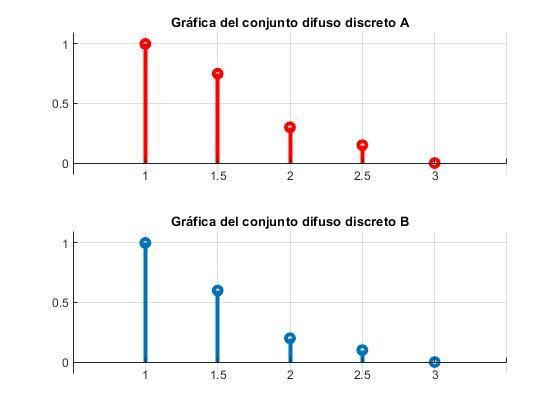

### Problema 6

Elabora una función que reciba el conjunto dominio x, el rango A, el rango B, de dos conjunto difusos. Un parámetro adicional que indique el tipo de unión que se quiere hacer (máximo, suma algebraica, suma acotada). La función debe regresar el rango de valores del conjunto resultante C. Además de imprimir una figura (3 por 1) donde se muestren las grafica de los tres conjunto involucrados.

Prueba esta función con el inciso d) de la imagen 4 (OperDif4). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso. Para esto:

- Reporta los tres tipos de uniones

- Combina las herramientas que ya tienes desarrolladas (de ser posible) para mostrar una gráfica con los tres tipos de uniones o desarrolla esta gráfica sin utilizar tus herramientas

En esta sección se espera tres llamadas a la función y un código para generar la cuarta gráfica. 

Llamadas a la función:

x = -2:0.1:14;
A = gaussmf(x,[2 8]);
B = gaussmf(x,[2 5]);
Problema6(x,A,B,0)  %0=máximo, 1=suma algebraica, 2=suma acotada,3=todas

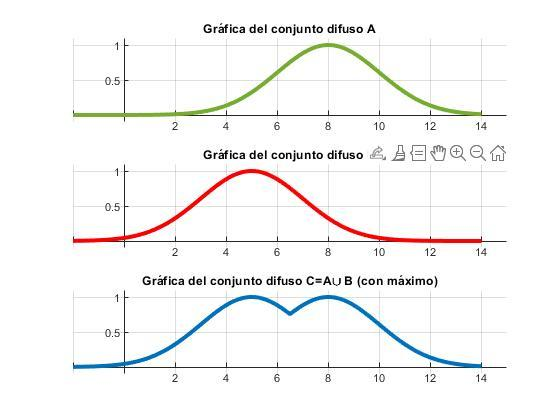

x = -2:0.1:14;
A = gaussmf(x,[2 8]);
B = gaussmf(x,[2 5]);
Problema6(x,A,B,1)  %0=máximo, 1=suma algebraica, 2=suma acotada,3=todas

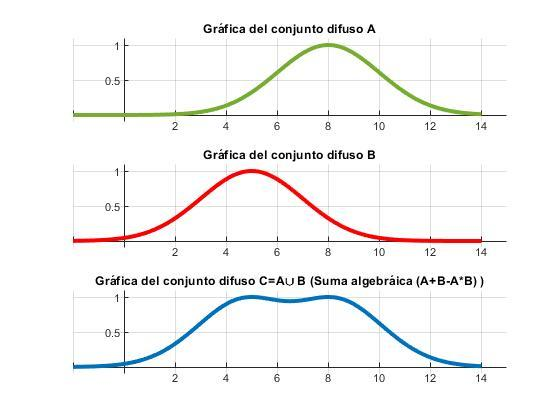

x = -2:0.1:14;
A = gaussmf(x,[2 8]);
B = gaussmf(x,[2 5]);
Problema6(x,A,B,2)  %0=máximo, 1=suma algebraica, 2=suma acotada,3=todas

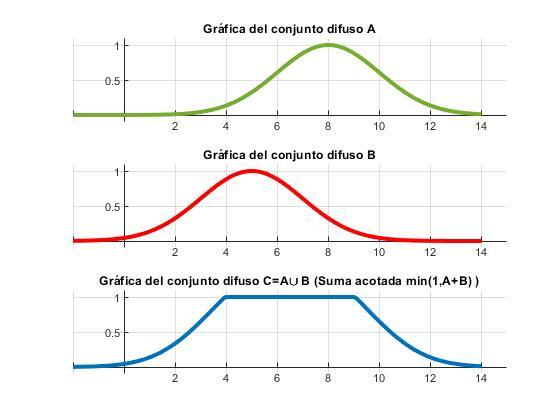

x = -2:0.1:14;
A = gaussmf(x,[2 8]);
B = gaussmf(x,[2 5]);
Problema6(x,A,B,3)  %0=máximo, 1=suma algebraica, 2=suma acotada,3=todas


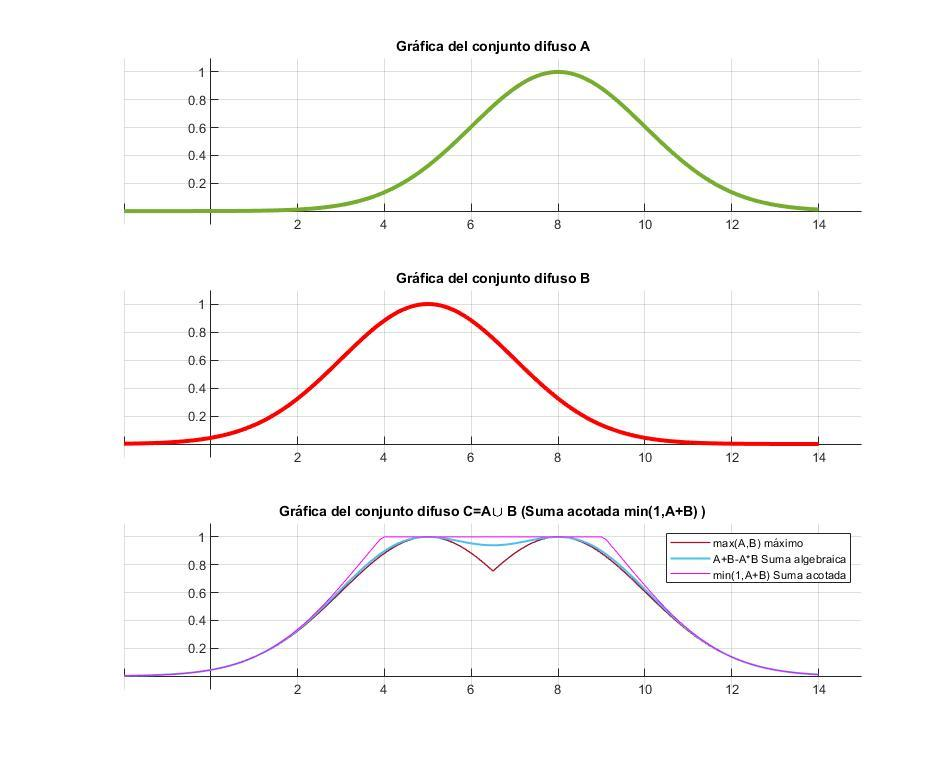

function [] = Problema6(x,A,B,condicion)

switch condicion
    case 0
        C=max(A,B);
        figure
        subplot(3,1,1)
        plot(x,A,'LineWidth',3,'Color','#77AC30');
        grid on
        axis([-2,15,-0.1,1.1])
        title('Gráfica del conjunto difuso A')
        h = gca;                            
        h.XAxisLocation = "origin";          
        h.YAxisLocation = "origin";          
        h.Box = "off"; 
        subplot(3,1,2)
        plot(x,B,'LineWidth',3,'Color','red');
        grid on
        axis([-2,15,-0.1,1.1])
        title('Gráfica del conjunto difuso B')
        h = gca;                             
        h.XAxisLocation = "origin";          
        h.YAxisLocation = "origin";         
        h.Box = "off"; 
        subplot(3,1,3)
        plot(x,C,'LineWidth',3);
        grid on
        axis([-2,15,-0.1,1.1])
        title('Gráfica del conjunto difuso C=A\cup B (con máximo)')
        h = gca;                             
        h.XAxisLocation = "origin";          
        h.YAxisLocation = "origin";          
        h.Box = "off"; 
    case 1
        C=A+B-A.*B;
        figure
        subplot(3,1,1)
        plot(x,A,'LineWidth',3,'Color','#77AC30');
        grid on
        axis([-2,15,-0.1,1.1])
        title('Gráfica del conjunto difuso A')
        h = gca;                            
        h.XAxisLocation = "origin";          
        h.YAxisLocation = "origin";          
        h.Box = "off"; 
        subplot(3,1,2)
        plot(x,B,'LineWidth',3,'Color','red');
        grid on
        axis([-2,15,-0.1,1.1])
        title('Gráfica del conjunto difuso B')
        h = gca;                             
        h.XAxisLocation = "origin";          
        h.YAxisLocation = "origin";         
        h.Box = "off"; 
        subplot(3,1,3)
        plot(x,C,'LineWidth',3);
        grid on
        axis([-2,15,-0.1,1.1])
        title('Gráfica del conjunto difuso C=A\cup B (Suma algebráica (A+B-A*B) )')
        h = gca;                             
        h.XAxisLocation = "origin";          
        h.YAxisLocation = "origin";          
        h.Box = "off"; 
    case 2
        C=min(1,A+B);
        figure
        subplot(3,1,1)
        plot(x,A,'LineWidth',3,'Color','#77AC30');
        grid on
        axis([-2,15,-0.1,1.1])
        title('Gráfica del conjunto difuso A')
        h = gca;                            
        h.XAxisLocation = "origin";          
        h.YAxisLocation = "origin";          
        h.Box = "off"; 
        subplot(3,1,2)
        plot(x,B,'LineWidth',3,'Color','red');
        grid on
        axis([-2,15,-0.1,1.1])
        title('Gráfica del conjunto difuso B')
        h = gca;                             
        h.XAxisLocation = "origin";          
        h.YAxisLocation = "origin";         
        h.Box = "off"; 
        subplot(3,1,3)
        plot(x,C,'LineWidth',3);
        grid on
        axis([-2,15,-0.1,1.1])
        title('Gráfica del conjunto difuso C=A\cup B (Suma acotada min(1,A+B) )')
        h = gca;                             
        h.XAxisLocation = "origin";          
        h.YAxisLocation = "origin";          
        h.Box = "off"; 
    case 3
        C=max(A,B);
        D=A+B-A.*B;
        E=min(1,A+B);
        figure
        subplot(3,1,1)
        plot(x,A,'LineWidth',3,'Color','#77AC30');
        grid on
        axis([-2,15,-0.1,1.1])
        title('Gráfica del conjunto difuso A')
        h = gca;                            
        h.XAxisLocation = "origin";          
        h.YAxisLocation = "origin";          
        h.Box = "off"; 
        subplot(3,1,2)
        plot(x,B,'LineWidth',3,'Color','red');
        grid on
        axis([-2,15,-0.1,1.1])
        title('Gráfica del conjunto difuso B')
        h = gca;                             
        h.XAxisLocation = "origin";          
        h.YAxisLocation = "origin";         
        h.Box = "off"; 
        
        subplot(3,1,3)
        plot(x,C,'LineWidth',1,'Color','#A2142F');
        hold on 
        plot(x,D,'LineWidth',1.5,'Color','#4DBEEE');
        hold on 
        plot(x,E,'LineWidth',.5,'Color','#FF00FF');
        legend('max(A,B) máximo','A+B-A*B Suma algebraica','min(1,A+B) Suma acotada')
        grid on
        axis([-2,15,-0.1,1.1])
        title('Gráfica del conjunto difuso C=A\cup B (Suma acotada min(1,A+B) )')
        h = gca;                             
        h.XAxisLocation = "origin";          
        h.YAxisLocation = "origin";          
        h.Box = "off"; 
    otherwise
        return      
end
end

### Problema 11

Implemente una gráfica donde indique ejemplos especificos para ilustrar

 

x = 0:0.1:10;
A = gaussmf(x,[2 5]);
B=1-A;
C = max(A, B); 
D = min(A,B);
figure
subplot(4,1,1)
plot(x,A,'LineWidth',3,'Color','#77AC30');
grid on
axis([-.5,11,-0.1,1.1])
title('Gráfica del conjunto difuso A')
h = gca;                            
h.XAxisLocation = "origin";          
h.YAxisLocation = "origin";          
h.Box = "off"; 
subplot(4,1,2)
plot(x,B,'LineWidth',3,'Color','red');
grid on
axis([-.5,11,-0.1,1.1])
title('Gráfica del conjunto difuso A(complemento) ')
h = gca;                             
h.XAxisLocation = "origin";          
h.YAxisLocation = "origin";         
h.Box = "off"; 
subplot(4,1,3)
plot(x,C,'LineWidth',3);
grid on
axis([-.5,11,-0.1,1.1])
title('Gráfica del conjunto difuso C=A\cup A(complemento)')
h = gca;                             
h.XAxisLocation = "origin";          
h.YAxisLocation = "origin";          
h.Box = "off"; 
subplot(4,1,4)
plot(x,D,'LineWidth',3','Color','#A2142F');
grid on
axis([-.5,11,-0.1,1.1])
title('Gráfica del conjunto difuso C=A\cap A(complemento)')
h = gca;                             
h.XAxisLocation = "origin";          
h.YAxisLocation = "origin";          
h.Box = "off";